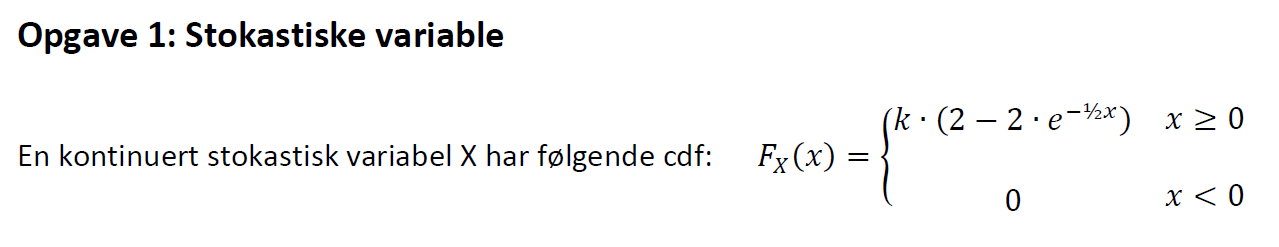

**a) Bestem k, så FX(x) opfylder betingelserne for at være en cdf.**

**Vi ved at en cdf ikke kan gå over 1 uanset x's værdi.**

**så, **$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=1$

hvilket betyder at vi kan sætte udtrykket lig med 1 og x ligmed uendelig og isolere k.

 

*k=1/2*

**b) Bestem den stokastiske variabels pdf fx(x), og tegn grafen for fx(x).**

**for at gå fra cdf til pdf skal cdf'en differentieres**

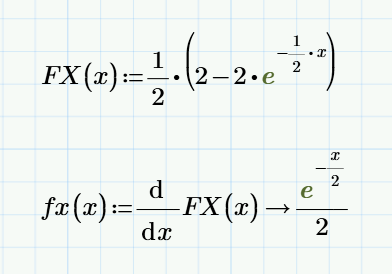


$$\mathrm{fx}\left(x\right)=\frac{e^{-\frac{x}{2}} }{2}$$


grafen ses for pdf'en  neden

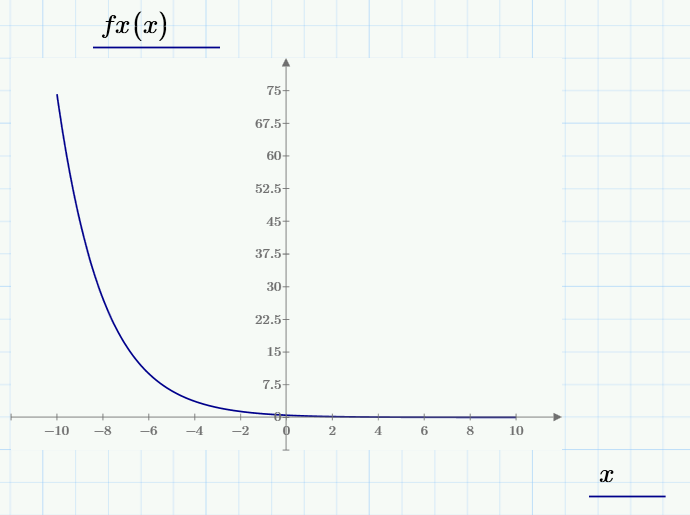

**c) Bestem sandsynligheden for at den stokastiske variabel X har en værdi mellem 1 og 2:**

**Pr(1 ≤ X ≤ 2).**

**vi bruger formlen **$\mathrm{Pr}\left(a\le x\le b\right)=\mathrm{Fx}\left(b\right)-\mathrm{Fx}\left(a\right)$


$$\mathrm{Pr}\left(1\le x\le 2\right)=0\ldotp 24$$


**d) Bestem middelværdien E[X] af den stokastiske variabel X.**

    

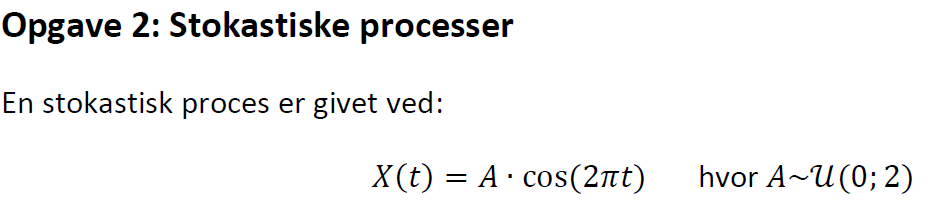

**a) Skitser tre realisationer af den stokastiske proces i intervallet t=[-2;2]**

$$temporal\_mean = 0$$

$$temporal\_var = 2.6189279661799728170749510560167$$

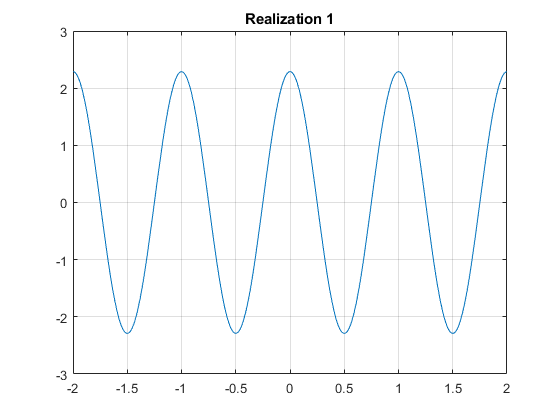

$$temporal\_mean = 0$$

$$temporal\_var = 1.54390889459731605173589443588$$

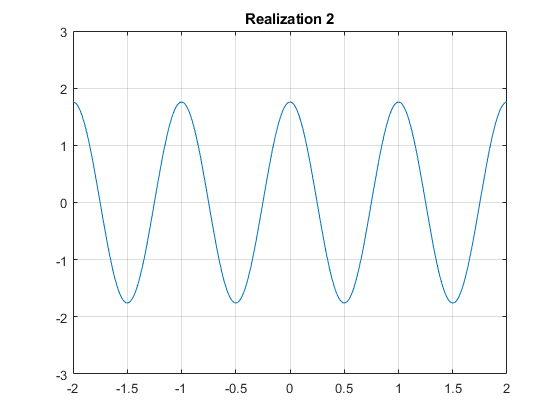

$$temporal\_mean = 0$$

$$temporal\_var = 3.4404865970969450234065171115485$$

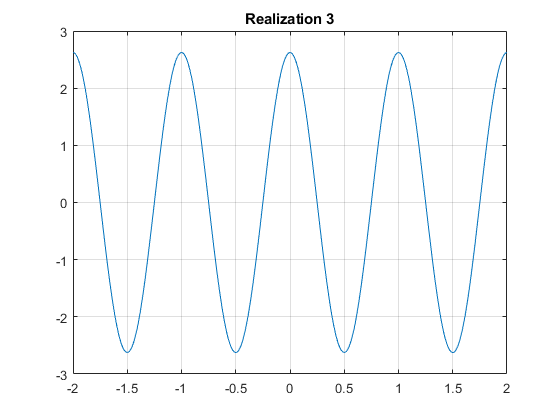

%Three realizations
A=makedist('Uniform','Lower',0,'Upper',2);
syms t;
T=5;
for i=1:3 %1:3 because we need 3 realizations
    Ap=A.random+1;
    Xt(t)=Ap*cos(2*pi*t);
    temporal_mean=(1/T)*int(Xt,(-T/2),(T/2))
    temporal_var=vpa((1/T)*int((Xt^2-temporal_mean^2),(-T/2),(T/2)))
    figure;
    fplot(Xt(t))
    grid
    title(['Realization ',num2str(i)])%axis title
    axis([-2,2,-3,3])%set values(length) for x and y axis

end

**b) Bestem den temporale middelværdi og varians af én realisation.**

**Værdierne findes i opgave 2a)**

**c) Bestem ensemple middelværdi og varians af den stokastiske proces.**

middelværdi for kontinueret uniform er $\frac{a+b}{2}$ 

så formlen ser således ud


$$E\left\lbrack \mathrm{Xt}\right\rbrack =E\left\lbrack A\right\rbrack \cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)=\frac{0+2}{2}\cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)=\mathrm{cos}\left(2\cdot \pi \cdot t\right)$$


ensemble_mean=((0+2)/2)*cos(2*pi*t)

$$ensemble\_mean = \cos\left(2\,\pi \,t\right)$$

Variansen for en kontinueret uniformfordeling er $\frac{{\left(b-a\right)}^2 }{12}$


$$\mathrm{var}\left(t\right)=\mathrm{var}\left\lbrack A\right\rbrack \cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)=\frac{{\left(2-0\right)}^2 }{12}\cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)=$$


ensemble_var=(((2-0)^2)/12)*cos(2*pi*t)

$$ensemble\_var = \frac{\cos\left(2\,\pi \,t\right)}{3}$$

ensemble mean: $\mathrm{cos}\left(2\cdot \pi \cdot t\right)$

ensemble var: $\frac{\mathrm{cos}\left(2\cdot \pi \cdot t\right)}{3}$

**d) Er den stokastiske proces WSS (Wide Sense Stationary)? Er den ergodisk?**

**Svarene skal begrundes.**

*Da tid tages i betragtning, kan vi antage at den stokastiske process IKKE er WSS*

*Da mean og variansen ændres når tid tages i betragtning er processen IKKE ergodisk*

# **Opgave 3: Sandsynlighedsregning**

**En producent af spændingsforsyninger tester de færdige apparater inden de forlader fabrikken. Til testen er udviklet en automatisk test.**

**Testen er imidlertid ikke helt fejlfri. Hvis et apparat testes positiv (godkendes), vil det kun i 90% af tilfældene faktisk overholde specifikationerne. Og hvis et apparat testes negativ (ikke godkendes), vil det kun være i 80% af tilfældene, at det ikke overholder specifikationerne. Samlet set godkendes 85% af alle apparaterne ved testen.**


$$T=\mathrm{Positiv}\;\mathrm{test}$$



$$\overline{T} =\;\mathrm{ikke}\;\mathrm{Positiv}\;\mathrm{test}$$



$$F=\mathrm{Funktionelt}\;\mathrm{apparat}$$



$$\bar{F} =\;\mathrm{ikke}\;\mathrm{Funktionelt}\;\mathrm{apparat}$$



$$\mathrm{Pr}\left(T|F\right)=0\ldotp 90$$



$$\mathrm{Pr}\left(\overline{T} \left|\overline{F} \right.\right)=0\ldotp 80$$



$$\mathrm{Pr}\left(T\right)=0\ldotp 85$$



$$\mathrm{Pr}\left(\overline{\;T} \right)=1-\mathrm{PR}\left(T\right)=1-0\ldotp 85=0\ldotp 15$$


**a) Hvad er sandsynligheden for at et apparat faktisk overholder specifikationerne, selvom det er testet negativ (ikke godkendt)?**


$$\mathrm{Pr}\left(F|\overline{\;T} \right)=1-\mathrm{Pr}\left(\overline{\;F} |\overline{\;T} \right)=1-0\ldotp 80=0\ldotp 20$$


**b) Hvad er sandsynligheden for at et apparat både overholder specifikationerne og testes positiv?**


$$\mathrm{Pr}\left(F\cap T\right)=\mathrm{Pr}\left(F|T\right)\cdot \mathrm{Pr}\left(T\right)=0\ldotp 90\cdot 0\ldotp 85=0\ldotp 765$$


**c) Hvor mange ud af 1000 producerede apparater må forventes ikke at overholde specifikationerne?**

Vi vil gerne finde $\mathrm{Pr}\left(\overline{\;F} \right)$ så vi finder $\mathrm{Pr}\left(F\right)$ og finder den komplimentære værdi derefter


$$\begin{array}{l}
\mathrm{Pr}\left(F\right)=\mathrm{Pr}\left(F\cap T\right)\cdot \mathrm{Pr}\left(F\cap \overline{\;T} \right)\\
\mathrm{Pr}\left(F\right)=\mathrm{Pr}\left(F|T\right)\cdot \mathrm{Pr}\left(T\right)+\mathrm{Pr}\left(F|\overline{\;T} \right)\cdot \mathrm{Pr}\left(\overline{\;T} \right)\\
\mathrm{Pr}\left(F\right)=0\ldotp 90\cdot 0\ldotp 85+0\ldotp 20\cdot 0\ldotp 15\\
\mathrm{Pr}\left(F\right)=0\ldotp 795\\
\mathrm{Pr}\left(\overline{\;F} \right)=1-\mathrm{Pr}\left(F\right)=1-0\ldotp 795=0\ldotp 205
\end{array}$$



$$1000\cdot 0\ldotp 205=205$$


*205 apparater forventes at overholde specifikationerne*

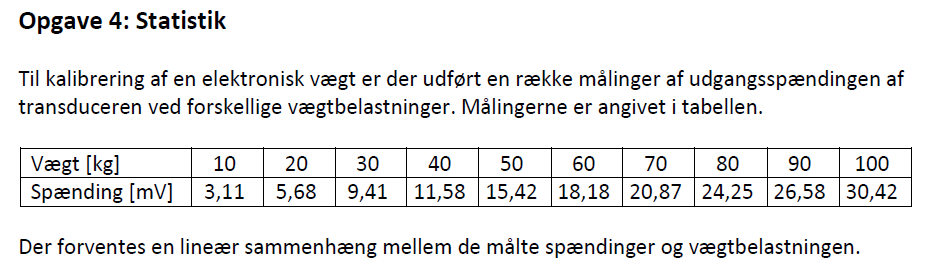

vaegt

vaegt=[10 20 30 40 50 60 70 80 90 100];
spaending=[3.11 5.68 9.41 11.58 15.42 18.18 20.87 24.25 26.58 30.42]

spaending =     3.1100    5.6800    9.4100   11.5800   15.4200   18.1800   20.8700   24.2500   26.5800   30.4200


**a) Plot data fra tabellen i et koordinatsystem.**

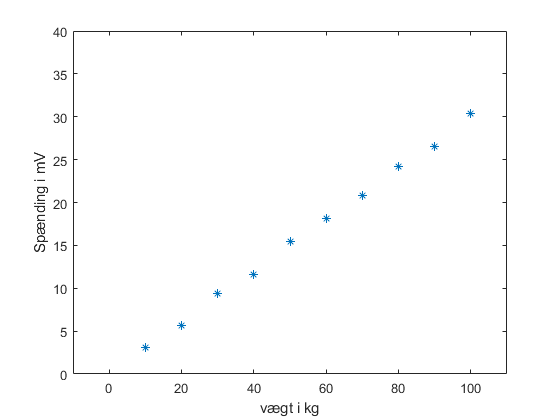

figure;
plot(vaegt,spaending,'*')
axis([-10 110 0 40])
xlabel('vægt i kg')
ylabel('Spænding i mV')

**b) Bestem ved hjælp af lineær regression en model for data. Beregn modellens parametre (hældningen af den lineære model og skæringen med y-aksen). Angiv hvorledes disse er beregnet.**


$$\mu {\;}_v =\frac{1}{10}\cdot \sum_{i=1}^{10} v_i$$


mu_v=(1/10)*sum(vaegt)

mu_v = 55


$$\mu {\;}_s =\frac{1}{10}\cdot \sum_{i=1}^{10} s_i$$


mu_s=(1/10)*sum(spaending)

mu_s = 16.5500

nu kan beta og alfa findes ved neden stående formler


$$\beta =\frac{\sum_{i=1}^{10} \left(v_i -\mu {\;}_v \right)\cdot \left(s_i -\mu {\;}_{s\;} \right)}{\sum_{i=1}^{10} {\left(v_i -\mu {\;}_v \right)}^2 }$$


for at udføre udregnignen i matlab opdeles tæller og nævner og regnes ud alene. herefter divideres de sammen.

beta_taeller= 0;
beta_naevner= 0;
for n=1:length(vaegt)%der er samme mængde data for vægt og spænding så det gør ikke nogen forskel hvilken der bruges
    beta_taeller = beta_taeller + (vaegt(n)-mu_v)*(spaending(n)-mu_s);
    beta_naevner = beta_naevner + (vaegt(n)-mu_v).^2;% every element is taken to the power of 2
end
beta = beta_taeller/beta_naevner%Dette er hældningen

beta = 0.3012

alfa findes ved at bruge nedenstående formel


$$\alpha =\mu {\;}_s -\beta \cdot \mu {\;}_v$$


alpha = mu_s-beta*mu_v%dette er skæringen

alpha = -0.0140

vi har nu fundet hældningen og skæringen og kan skrive formlen for den bedste rette linje således


$$S=-0\ldotp 0140+0\ldotp 3012\cdot V+\varepsilon$$
 

Skæringen er -0.0140

hældnignen er 0.3012

**c) Indtegn den rette linje fra modellen i b) i plottet fra a).**

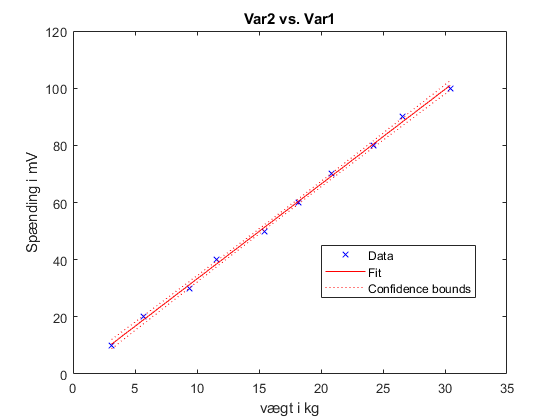

tbl = table(spaending' , vaegt');
mdl = fitlm(tbl,'linear');
figure;
plot(mdl)
xlabel('vægt i kg')
ylabel('Spænding i mV')

**d) Beregn residualerne for data og indtegn disse i et residual-plot.**

Tager vi den originale formel 


$$S=\alpha +\beta \cdot V+\varepsilon$$


kan vi isolere epsilon, og ender derfor med 


$$\varepsilon {\;}_i =S_i -\alpha +\beta \cdot V_i$$


epsilon = spaending-(alpha+(beta*vaegt))

epsilon =     0.1124   -0.3293    0.3891   -0.4525    0.3758    0.1242   -0.1975    0.1709   -0.5107    0.3176


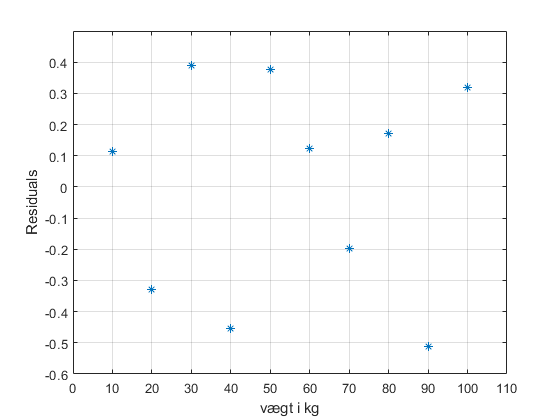

figure;
plot(vaegt,epsilon,'*')
axis([0, 110,-0.6 0.5])
xlabel('vægt i kg')
ylabel('Residuals')

grid on

**e) Beregn 95% konfidensintervallet for hældningen af den rette linje i modellen.**


$$S_r^2 =\frac{1}{n-2}\cdot \;\sum_{i=1}^n {\left(y_i -\left(\alpha +\beta \cdot x_i \right)\right)}^2$$


sr2=(1)/(length(vaegt)-2)*sum((spaending-(alpha+beta*vaegt)).^2);


$$S_{\mathrm{xx}} =\;\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2$$


sxx=sum((vaegt-mu_v).^2);

vi bruger formlen 


$$t_0 =\textrm{tinv}\left(1-\frac{0\ldotp 05}{2},n-2\right)=\textrm{tinv}\left(0\ldotp 975,n-2\right)$$


t0=tinv(0.975,length(vaegt)-2)

t0 = 2.3060

herefter kan den nedre og øvre grænse findes


$${\beta \;}_- =\beta -t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}$$


Beta_nedre=beta-t0*sqrt(sr2/sxx)

Beta_nedre = 0.2919


$${\beta \;}_+ =\beta +t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}$$


Beta_oevre=beta+t0*sqrt(sr2/sxx)

Beta_oevre = 0.3104

**f) Ud fra svarene i spørgsmål d) og e), hvad vil du så konkludere om antagelsen om linearitet mellem vægtbelastningen og udgangsspændingen på transduceren? Svaret skal begrundes.**


$$\Delta \;\beta =t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}=0\ldotp 0093$$


beta_delta=t0*sqrt(sr2/sxx)

beta_delta = 0.0093


$$\frac{\Delta \;\beta }{\beta \;}=\frac{0\ldotp 0093}{0\ldotp 3012}=0\ldotp 0307$$


beta_delta/beta

ans = 0.0307

*Ud fra risidual plotet kan vi se at punkterne ligger tilfældigt om X-aksen, hvilket er en indikator om at en linæer model ville kunne antages at være passende.*

*forholdet mellem beta og delta beta er småt, hvilket betyder at den udregnede beta er rimelig præcis, som betyder at vi med god antagelse kan sige at der er en linearitet mellem vægt og spænding.*